## Group 9 - Quantitative Models for Data Science

### **Abalone Dataset**

*We consider measurements of a sample of abalones.The age of abalone is determined by cutting the shell through the cone, staining it, and counting the number of rings through a microscope, which is a boring and time-consuming task. Other measurements, which are easier to obtain, are used to predict the age.*

### Group Members

- *Matteo Spadaccia*

- *Valerio Romano Cadura*

- *Dan Mark Tolod*

- *Filippo Castello*

***Task 1***

*We start by importing the data*

Abalonedata = readtable('Abalone_data.xlsx');

We split our dataset into training and testing samples. We decided to use approximately the $90%$% of the data in order to train the model and the remaining $10%$% to test it.

We want to separate the the training and the testing data randomly in order to avoid biasing the data.

% Obtaining X size
[m,n] = size(Abalonedata);

Partition = 0.90;

% we added a random seed in order to obtain always the same permutations and results
rng('default')
s = rng

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


% uncomment if needed

% randperm(n) returns a row vector containing a random permutation of the integers from 1 to n without repeating elements
positions = randperm(m);
Data_train = Abalonedata(positions(1:round(Partition*m)),:);
Data_test = Abalonedata(positions(round(Partition*m)+1:end),:);

Then we want to split our input variables from our output variable

X_train = Data_train(:,1:4);
X_test = Data_test(:,1:4);
Y_train = Data_train(:,5);
Y_test = Data_test(:,5);

Now that we have our train and test sets, we want to plot the train data in order to visualize the behaviour of each input variable.

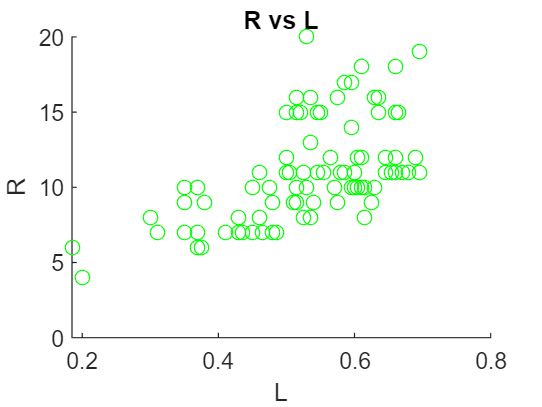

L_train = table2array(X_train(:,1));
D_train = table2array(X_train(:,2));
H_train = table2array(X_train(:,3));
W_train = table2array(X_train(:,4));
R_train = table2array(Y_train);

%Plotting the variables
hold off

scatter(L_train,R_train, "green")
ylabel('R')
xlabel('L')
title('R vs L')

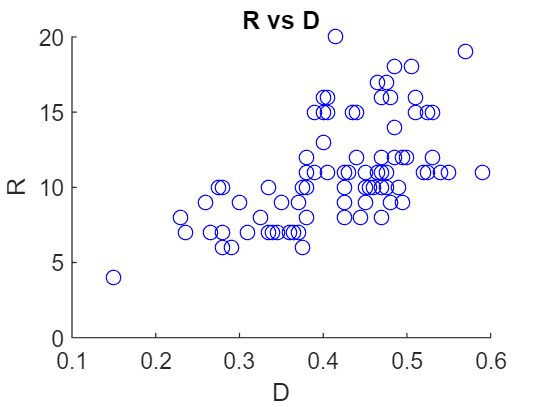


scatter(D_train,R_train,'blue')
ylabel('R')
xlabel('D')
title('R vs D')

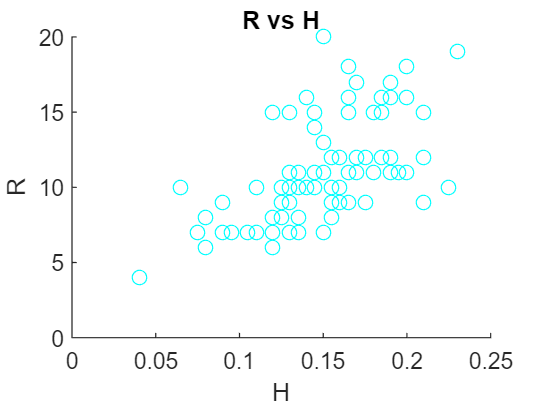


scatter(H_train, R_train, "cyan")
ylabel('R')
xlabel('H')
title('R vs H')

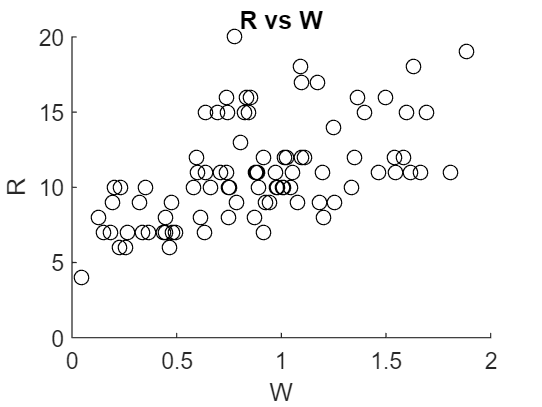


scatter(W_train, R_train, "black")
ylabel('R')
xlabel('W')
title('R vs W')

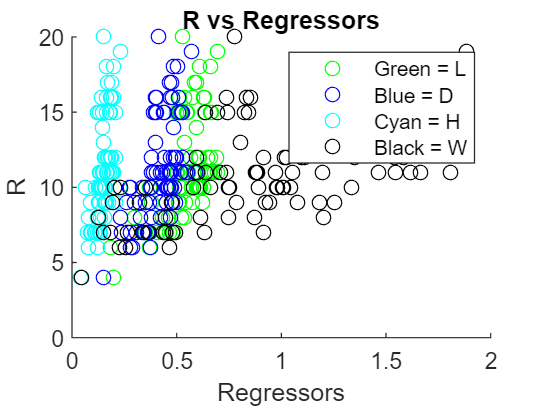



scatter(L_train, R_train, 'green')
hold on
scatter(D_train, R_train, 'blue')
scatter(H_train, R_train, 'cyan')
scatter(W_train, R_train, "black")
ylabel('R')
xlabel('Regressors')
title('R vs Regressors')
legend('Green = L','Blue = D', 'Cyan = H', 'Black = W')
hold off

Observing the scatterplots, we can confirm that, as it was possible to hypothesize a priori, the age of the abalone and therefore the number of its rings is more or less proportional to its weight, therefore basically to its volume.

Concerning the other regressors, we have an indirect corrispondence due to the volume-age one, but $H$ proportionality is the most hard to get. 

We now proceed applying the least-squares method to each pair regressor-response.

We start with the pair $L$- $y%$

%Constructing the design matrix X = [1 x]
X_L = [ones(length(L_train),1), L_train];
XtX_L = X_L'*X_L;
XtX_inv_L = inv(XtX_L);
Xty_L = X_L'*R_train;
beta_hat_L = XtX_inv_L*Xty_L;
beta0_L = beta_hat_L(1);
beta1_L = beta_hat_L(2);

y_hat_L = X_L*beta_hat_L;
epsilon_hat_L = R_train - y_hat_L;
epsilon_hat_squared_L = epsilon_hat_L.^2;
RMSE_L = sqrt(mean(epsilon_hat_squared_L));
l_reg_L = @(x) beta0_L + beta1_L*x;

We now plot the regression line for the pair $L$- $y%$

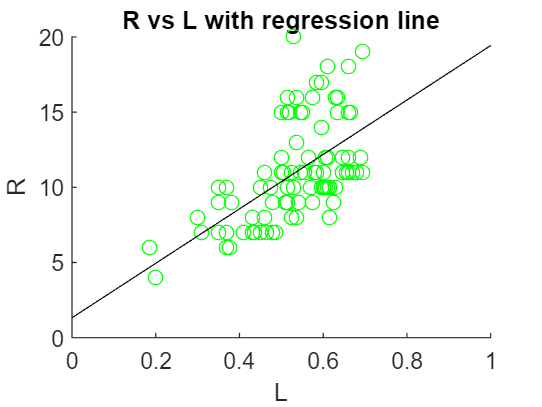

scatter(L_train,R_train, "green")
hold on
fplot(l_reg_L, [0 1],'black')
ylabel('R')
xlabel('L')
title('R vs L with regression line')
hold off


beta0_L

beta0_L = 1.3262

beta1_L

beta1_L = 18.1002


disp('The root mean squared error R vs L is:')

The root mean squared error R vs L is:


RMSE_L

RMSE_L = 2.7158

The second pair is $D$- $y%$

%Constructing the design matrix X = [1 x]
X_D = [ones(length(D_train),1), D_train];
XtX_D = X_D'*X_D;
XtX_inv_D = inv(XtX_D);
Xty_D = X_D'*R_train;
beta_hat_D = XtX_inv_D*Xty_D;
beta0_D = beta_hat_D(1);
beta1_D = beta_hat_D(2);

y_hat_D = X_D*beta_hat_D;
epsilon_hat_D = R_train - y_hat_D;
epsilon_hat_squared_D = epsilon_hat_D.^2;
RMSE_D = sqrt(mean(epsilon_hat_squared_D));


l_reg_D = @(x) beta0_D + beta1_D*x;

We now plot the regression line for the pair $D$- $y%$

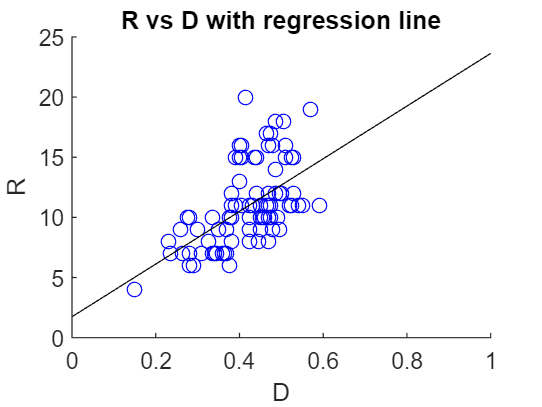

scatter(D_train,R_train, "blue")
hold on
fplot(l_reg_D, [0 1],'black')
ylabel('R')
xlabel('D')
title('R vs D with regression line')
hold off


beta0_D

beta0_D = 1.7416

beta1_D

beta1_D = 21.8880


disp('The root mean squared error R vs D is:')

The root mean squared error R vs D is:


RMSE_D

RMSE_D = 2.7604

The third pair is $H$- $y%$

%Constructing the design matrix X = [1 x]
X_H = [ones(length(H_train),1), H_train];
XtX_H = X_H'*X_H;
XtX_inv_H = inv(XtX_H);
Xty_H = X_H'*R_train;
beta_hat_H = XtX_inv_H*Xty_H;
beta0_H = beta_hat_H(1);
beta1_H = beta_hat_H(2);

y_hat_H = X_H*beta_hat_H;
epsilon_hat_H = R_train - y_hat_H;
epsilon_hat_squared_H = epsilon_hat_H.^2;
RMSE_H = sqrt(mean(epsilon_hat_squared_H));


l_reg_H = @(x) beta0_H + beta1_H*x;

We now plot the regression line for the pair $H$- $y%$

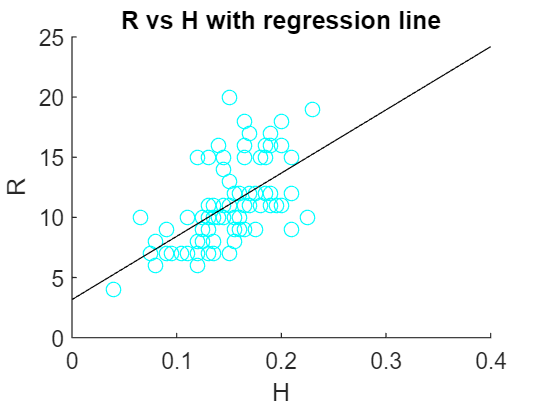

scatter(H_train,R_train, "cyan")
hold on
fplot(l_reg_H, [0 0.4],'black')
ylabel('R')
xlabel('H')
title('R vs H with regression line')
hold off


beta0_H

beta0_H = 3.1692

beta1_H

beta1_H = 52.5592


disp('The root mean squared error R vs H is:')

The root mean squared error R vs H is:


RMSE_H

RMSE_H = 2.6924

The final pair is $W$- $y%$

%Constructing the design matrix X = [1 x]
X_W = [ones(length(W_train),1), W_train];
XtX_W = X_W'*X_W;
XtX_inv_W = inv(XtX_W);
Xty_W = X_W'*R_train;
beta_hat_W = XtX_inv_W*Xty_W;
beta0_W = beta_hat_W(1);
beta1_W = beta_hat_W(2);

y_hat_W = X_W*beta_hat_W;
epsilon_hat_W = R_train  - y_hat_W;
epsilon_hat_squared_W = epsilon_hat_W.^2;
RMSE_W = sqrt(mean(epsilon_hat_squared_W));

l_reg_W = @(x) beta0_W + beta1_W*x;

Finally we plot the regression line for the $W$- $y%$

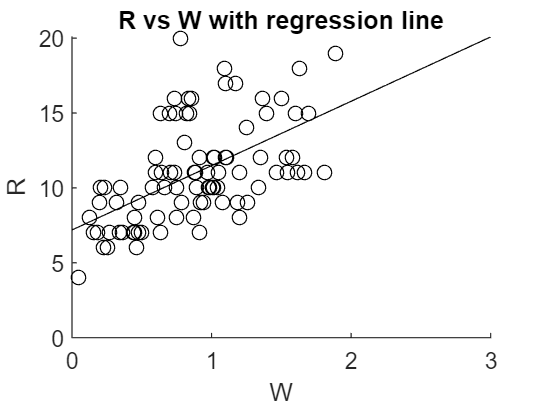

scatter(W_train,R_train, "black")
hold on
fplot(l_reg_W, [0 3],'black')
ylabel('R')
xlabel('W')
title('R vs W with regression line')
hold off

beta0_W

beta0_W = 7.1921

beta1_W

beta1_W = 4.2962

disp('The root mean squared error R vs W is:')

The root mean squared error R vs W is:


RMSE_W

RMSE_W = 2.7815

$\beta_{0}$ is the constant y-intercept of the line and $\beta_{1}$ its angular coefficient in each case. We can see that the $RMSE$ are comparable, even if $H$ has a slightly higher value, within the regressors: maybe a multivariate regression could be a good idea with this dataset

We now try to make some predictions with the sample we extracted from the dataset.

Y_pred_L = l_reg_L(table2array(X_test(:,1)));
Y_pred_D = l_reg_D(table2array(X_test(:,2)));
Y_pred_H = l_reg_H(table2array(X_test(:,3)));
Y_pred_W = l_reg_W(table2array(X_test(:,4)));

len = length(table2array(X_test(:,1)));

disp('The residual sum of squares of the predictions is:')

The residual sum of squares of the predictions is:


SSoR_L = sum((Y_pred_L-table2array(Y_test)).^2)

SSoR_L = 91.6470

SSoR_D = sum((Y_pred_D-table2array(Y_test)).^2)

SSoR_D = 95.8075

SSoR_H = sum((Y_pred_H-table2array(Y_test)).^2)

SSoR_H = 88.3630

SSoR_W = sum((Y_pred_W-table2array(Y_test)).^2)

SSoR_W = 94.4634


disp('The mean squared error of the predictions is:')

The mean squared error of the predictions is:


MSE_L = SSoR_L/ len

MSE_L = 9.1647

MSE_D = SSoR_D/ len

MSE_D = 9.5808

MSE_H = SSoR_H/ len

MSE_H = 8.8363

MSE_W = SSoR_W/ len

MSE_W = 9.4463


disp('The root mean squared error of the prediction is:')

The root mean squared error of the prediction is:


RMSE_L = sqrt(MSE_L)

RMSE_L = 3.0273

RMSE_D = sqrt(MSE_D)

RMSE_D = 3.0953

RMSE_H = sqrt(MSE_H)

RMSE_H = 2.9726

RMSE_W = sqrt(MSE_W)

RMSE_W = 3.0735

We discovered that generally all the predictor variables are good linear regressors. We want to check whether using multiple regressor for the prediction decrease the root mean squared error.

**Task 2**

We now consider the linear model with all the predictor variables.

We merge all the scatterplots using subplot.

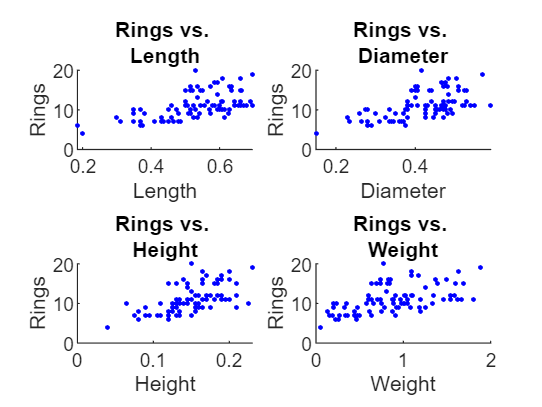

labels = ["Length" "Diameter" "Height" "Weight" "Rings"];
figure()
for i = 1:4
    subplot(2,2,i)
    scatter(table2array(X_train(:,i)),R_train,'b.')
    title(['Rings vs. ' labels(i)])
    xlabel(labels(i))
    ylabel('Rings')
end

It appears that the relation between the length and the rings appear to be linear, the same happens regarding the pair height rings, the other two variables could be either linear or curvilinear.

We may want to compute the standard deviation of each regressor.

std_length = std(L_train)

std_length = 0.1089

std_diameter = std(D_train)

std_diameter = 0.0871

std_height = std(H_train)

std_height = 0.0381

std_weight = std(W_train)

std_weight = 0.4367

We notice that the weight is the regressor with highest variation followed by the length. 

*We now try to determine the best linear model that fits the data, among those who satisfy:*

$M_i = \beta_0 + \beta_1 \ell_i + \beta_2 d_i + \beta_3 h_i + \beta_4 w_i + \varepsilon_i$*, *$i = 1, \dots, 90$*,*

*with m = 100 is the number of observations and *$l_i, d_i, h_i, w_i, R_i$*  refer to the length, diameter, height and weight of the abalone. *

*We introduce:*

$\mathbf y = \left[\matrix{M_1 \cr \vdots \cr M_{90}}\right]$*, the vector of the response variable;*

$X= \left[\matrix{1 & \ell_1 & d_1 & h_1 & w_1 \cr \vdots & \vdots &\vdots & \vdots & \vdots \cr 1 & \ell_{90} & d_{90} & h_{90} & w_{90}}\right]$*, the design matrix;*

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \beta_3 \cr \beta_4}\right]$*, the vector of coefficients;*

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_{90}}\right]$*, the vector of residuals.*

*We need to minimize the residual sum of squares *$||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2 =: f(\mathbf \beta)$*,*

*that is, to find *$\mathbf \beta$* that minimizes the distance bet     ween *$\mathbf y$* and *$X\mathbf \beta$*. This is equivalent to solving the linear system *$\mathbf y = X\mathbf \beta$* in the least-squares sense which, in turn, is equivalent to solving the normal equation*

$X^TX \mathbf \beta = X^T \mathbf y$*.*

*If *$X$* has linearly independent columns (i.e., *$X^TX$* is invertible), then the best linear model fitting the data has coefficients:*

$\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$*.*

We proceed we the multivariate regression.

disp('Multivariate linear regression with all the regressor:')

Multivariate linear regression with all the regressor:


m = length(R_train);
% Defining the design matrix
X_temp = [ones(m,1) table2array(X_train)];
% Solving the linear system in the least-squares sense
beta_hat_temp = X_temp\R_train % '\' solves the linear system if possible

beta_hat_temp =     0.4787
   11.0449
   -0.0359
   38.7528
   -1.2830


% Making predictions           % if not possible it solves it in l-s-sense
y_hat_temp = X_temp*beta_hat_temp;
% Computing Residuals
epsilon_hat_temp = table2array(Y_train)  - y_hat_temp;
% Residual Sum of Squares
epsilon_hat_squared_temp = epsilon_hat_temp.^2;
disp('The root mean squared error on the train is:')

The root mean squared error on the train is:


RMSE_all = sqrt(mean(epsilon_hat_squared_temp))

RMSE_all = 2.6443

We can easily see that the result is slightly better than the one obtained with the considering the single predictor regression, but there is no major improvement, we want to check that the latter happens with the predictions.

l_multi_inter = beta_hat_temp(1);
l_multi_L = @(x) beta_hat_temp(2)*x;
l_multi_D = @(x) beta_hat_temp(3)*x;
l_multi_H = @(x) beta_hat_temp(4)*x;
l_multi_W = @(x) beta_hat_temp(5)*x;


Y_pred_multivariate = l_multi_inter + l_multi_L(table2array(X_test(:,1))) + l_multi_D(table2array(X_test(:,2))) + l_multi_H(table2array(X_test(:,3))) + l_multi_W(table2array(X_test(:,4)));

disp('The residual sum of squares of the predictions is:')

The residual sum of squares of the predictions is:


SSoR_multivariate = sum((Y_pred_multivariate - table2array(Y_test)).^2)

SSoR_multivariate = 88.9152


disp('The mean squared error of the predictions is:')

The mean squared error of the predictions is:


MSE_multivariate = SSoR_multivariate/ len

MSE_multivariate = 8.8915


disp('The root mean squared error of the prediction is:')

The root mean squared error of the prediction is:


RMSE_multivariate = sqrt(MSE_multivariate)

RMSE_multivariate = 2.9819

We can see that when predicting the model does a good job with the root mean squared error similar to the one observed in the single variable case considering the shell length predictor.

Now we want to try without considering the W regressor, the one with highest standard deviation.

disp('Multivariate linear regression considering L, D and H:')

Multivariate linear regression considering L, D and H:


% Setting up the matrix with the first three regressors L, D and H
X_LDH_train = X_train(:,1:3);
% Defining the Design Matrix
X_temp = [ones(m,1) table2array(X_LDH_train)];
% Solving in the least squares sense
beta_hat_temp = X_temp\R_train

beta_hat_temp =     1.8027
   10.1145
   -2.4843
   32.5295


% Making predictions 
y_hat_temp = X_temp*beta_hat_temp;
% Computing Residuals
epsilon_hat_temp = table2array(Y_train) - y_hat_temp;
% Residual Sum of Squares
epsilon_hat_squared_temp = epsilon_hat_temp.^2;
disp('The root mean squared error on the train is:')

The root mean squared error on the train is:


RMSE_LDH = sqrt(mean(epsilon_hat_squared_temp))

RMSE_LDH = 2.6500

Using three regressor instead of four removing W yields a slightly worse result. 

Let's check what happen when making predictions.

l_multi_inter = beta_hat_temp(1);
l_multi_L = @(x) beta_hat_temp(2)*x;
l_multi_D = @(x) beta_hat_temp(3)*x;
l_multi_H = @(x) beta_hat_temp(4)*x;


Y_pred_LDH = l_multi_inter + l_multi_L(table2array(X_test(:,1))) + l_multi_D(table2array(X_test(:,2))) + l_multi_H(table2array(X_test(:,3)));

disp('The residual sum of squares of the predictions is:')

The residual sum of squares of the predictions is:


SSoR_LDH = sum((Y_pred_LDH - table2array(Y_test)).^2)

SSoR_LDH = 89.0738


disp('The mean squared error of the predictions is:')

The mean squared error of the predictions is:


MSE_LDH = SSoR_LDH/ len

MSE_LDH = 8.9074


disp('The root mean squared error of the predictions is:')

The root mean squared error of the predictions is:


RMSE_LDH = sqrt(MSE_LDH)

RMSE_LDH = 2.9845

When making predictions we obtain an error higher than the ones observed before both in the single variable case and in the multivariate, hence we could say that considering the first three regressors does not change that much.

We can try the last time using only the shell lenght and the height.

disp('Multivariate linear regression considering L and H:')

Multivariate linear regression considering L and H:


% Setting up the matrix with the first three regressors L, D and H
X_LH_train = [table2array(X_train(:,1)) table2array(X_train(:,3))];
% Defining the Design Matrix
X_temp = [ones(m,1) X_LH_train];
% Solving in the least squares sense
beta_hat_temp = X_temp\R_train

beta_hat_temp =     1.7331
    8.6794
   31.0948


% Making predictions 
y_hat_temp = X_temp*beta_hat_temp;
% Computing Residuals
epsilon_hat_temp = table2array(Y_train) - y_hat_temp;
% Residual Sum of Squares
epsilon_hat_squared_temp = epsilon_hat_temp.^2;
disp('The root mean squared error on the train is:')

The root mean squared error on the train is:


RMSE_LH = sqrt(mean(epsilon_hat_squared_temp))

RMSE_LH = 2.6509

Using the length and the height we obtain a result similar to the one obtained using all the regressor variables. We want to see what happen when making predictions.

l_multi_inter = beta_hat_temp(1)

l_multi_inter = 1.7331

l_multi_L = @(x) beta_hat_temp(2)*x;
l_multi_H = @(x) beta_hat_temp(3)*x;


Y_pred_LH = l_multi_inter + l_multi_L(table2array(X_test(:,1))) + l_multi_H(table2array(X_test(:,3)));

disp('The residual sum of squares of the predictions is:')

The residual sum of squares of the predictions is:


SSoR_LH = sum((Y_pred_LH - table2array(Y_test)).^2)

SSoR_LH = 89.7193


disp('The mean squared error of the predictions is:')

The mean squared error of the predictions is:


MSE_LH = SSoR_LH/ len

MSE_LH = 8.9719


disp('The root mean squared error of the predictions is:')

The root mean squared error of the predictions is:


RMSE_LH = sqrt(MSE_LH)

RMSE_LH = 2.9953

Again there are no significant improvements, hence we can say that in general the multivariate regression with all the regressor is the one more stable and yielding a consistent result. 

In the next section we want to find the best curvilinear model to fit the data and describe the relationship between the regressors 

labels = ["Length" "Diameter" "Height" "Weight" "Rings"];
figure()
for i = 1:4
    subplot(2,2,i)
    scatter(table2array(X_train(:,i)),R_train,'b.')
    title(['Rings vs. ' labels(i)])
    xlabel(labels(i))
    ylabel('Rings')
end

We may also use alternative linear models to suit the data we have, based on earlier graphs produced by single linear regression, the linear models performed reasonably well. We could say that a polynomial should fit the data well in the height-rings and diameter-rings pairs scatterplot. Therefore, we will use a polynomial equation to determine which non-linear model best fits all of the previously shown scatterplots. 

*This can be achieved by transforming data, i.e., applying suitable functions to the observations in the response and in the predictor variable. In this way, we can write a general linear model as*

$g(y_i) = \beta_0 + \beta_1 f_1(x_i) + \beta_2 f_2(x_i) + \cdots \beta_n f_n(x_i) + \epsilon_i, \, i = 1, \dots, 90$*.*

*The functions *$f_1, \dots, f_n, g$* determine the shape of the fitting curve.*

*The model above can be written as *$\mathbf y = X\mathbf \beta + \mathbf \epsilon$*, with*

$\mathbf y = \left[\matrix{g(y_1) \cr \vdots \cr g(y_{90})}\right]$*, the vector of the response variable;*

$X= \left[\matrix{1 & f_1(x_1) & f_2(x_1) & \cdots & f_n(x_1) \cr \vdots & \vdots &\vdots & \ddots & \vdots \cr 1 & f_1(x_{90}) & f_2(x_{90}) & \cdots & f_n(x_{90})}\right]$*, the design matrix;*

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \vdots \cr \beta_{m}}\right]$*, the vector of coefficients;*

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_{90}}\right]$*, the vector of residuals.*

*Therefore, we can determine the best coefficients for these general models solving the normal equation:*

$X^TX \mathbf \beta = X^T \mathbf y$*.*

We can find the right polynomial by looping using different polynomial equation and check for the one that yields the smaller errors.

Here I try with polynomials of degree $\le 5$.

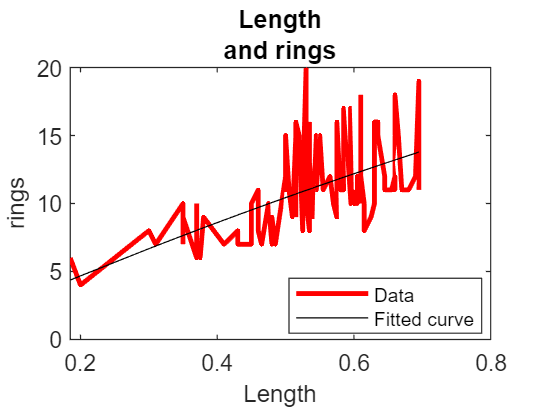

The root mean squared error for this polynomial approximation on the train is:


RMSE_poly = 3.6445

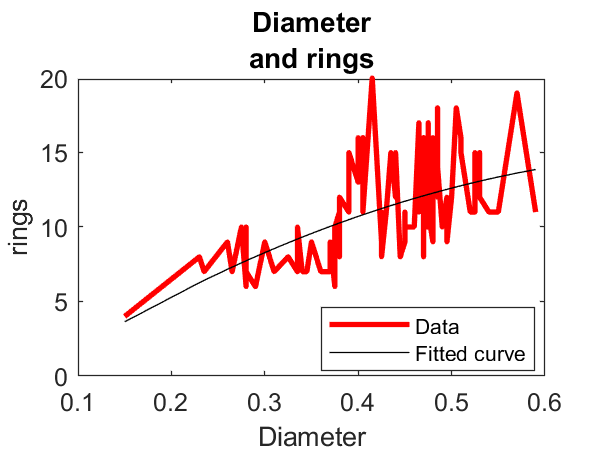

The root mean squared error for this polynomial approximation on the train is:


RMSE_poly = 3.6239

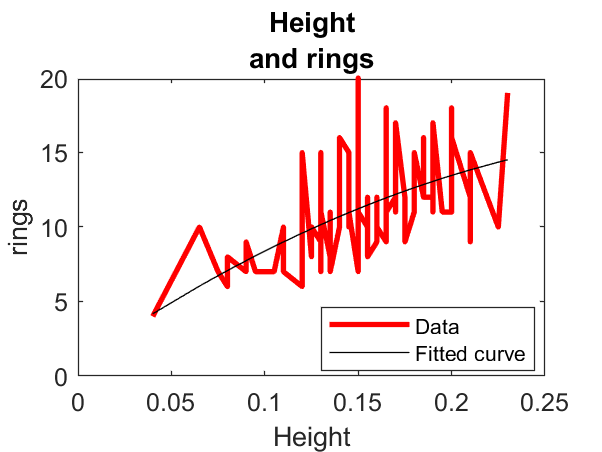

The root mean squared error for this polynomial approximation on the train is:


RMSE_poly = 3.6937

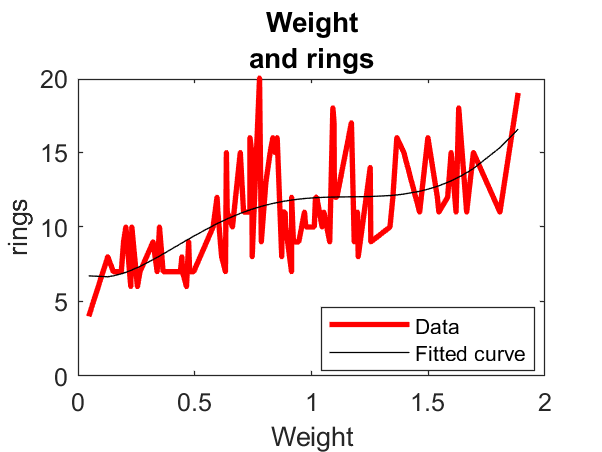

The root mean squared error for this polynomial approximation on the train is:


RMSE_poly = 3.6144

labels = ["Length" "Diameter" "Height" "Weight" "Rings"];

RMSEs_poly = [];

for i=1:4
    RMSEs_temp = [];
    table = [X_train(:,i) Y_train];
    sorted_table = sortrows(table,1);
    X_train_i = table2array(sorted_table(:,1));
    y_train_i = table2array(sorted_table(:,2));


    for j=1:5
        if j == 1 
            design_poly = [ones(m,1) X_train_i];
        elseif j == 2
            design_poly = [ones(m,1) X_train_i X_train_i.^2];
        elseif j == 3
            design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3];
        elseif j == 4
            design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4];
        else
            design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4 X_train_i.^5];
        end

        beta_hat_poly = design_poly\y_train_i;
        y_hat_poly = design_poly*beta_hat_poly;
        epsilon_hat_poly = table2array(Y_train) - y_hat_poly;
        % Residual Sum of Squares
        SSoR_poly = epsilon_hat_poly.^2;
        % Root Mean Squared Error
        RMSE_poly = sqrt(mean(SSoR_poly));
        RMSEs_temp(end+1) = RMSE_poly;
    
    end

    [val, idx] = min(RMSEs_temp);
    RMSEs_poly(end+1) = idx;
    RMSEs_poly(end+1) = val;
    if idx == 1 
        design_poly = [ones(m,1) X_train_i];
    elseif idx == 2
        design_poly = [ones(m,1) X_train_i X_train_i.^2];
    elseif idx == 3
        design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3];
    elseif idx == 4
        design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4];
    else
        design_poly = [ones(m,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4 X_train_i.^5];
    end

    beta_hat_poly = design_poly\y_train_i;
    y_hat_poly = design_poly*beta_hat_poly;
    epsilon_hat_poly = table2array(Y_train) - y_hat_poly;
    % Residual Sum of Squares
    SSoR_poly = epsilon_hat_poly.^2;
    % Root Mean Squared Error
    RMSE_poly = sqrt(mean(SSoR_poly));
    figure()

    plot(X_train_i,y_train_i,'r','MarkerSize',3,'LineWidth',2)
    title([labels(i) "and rings"])
    xlabel(labels(i),'FontSize',10)
    ylabel('rings','FontSize',10)
    hold on
    plot(X_train_i,y_hat_poly,'black')
    legend('Data','Fitted curve','FontSize',8,'Location','best')
    hold off
    disp('The root mean squared error for this polynomial approximation on the train is:')
    RMSE_poly = val



end

We can play with the function a bit and try to find the best polynomial to fit the data. 

Displaying the variable *RMSE_poly* we can see how the code minimizing the $RMSE$ between different degree of polynomials chose the one yielding the minimum $RMSE$ among all of them. 

  disp('The degree chosen for the variable length is:')

The degree chosen for the variable length is:


  RMSEs_poly(1)

ans = 2

  disp('Yielding a RMSE of:')

Yielding a RMSE of:


  RMSEs_poly(2)

ans = 3.6445


  disp('The degree chosen for the variable diameter is:')

The degree chosen for the variable diameter is:


  RMSEs_poly(3)

ans = 2

  disp('Yielding a RMSE of:')

Yielding a RMSE of:


  RMSEs_poly(4)

ans = 3.6239


  disp('The degree chosen for the variable height is:')

The degree chosen for the variable height is:


  RMSEs_poly(5)

ans = 2

  disp('Yielding a RMSE of:')

Yielding a RMSE of:


  RMSEs_poly(6)

ans = 3.6937


  disp('The degree chosen for the variable weight is:')

The degree chosen for the variable weight is:


  RMSEs_poly(7)

ans = 5

  disp('Yielding a RMSE of:')

Yielding a RMSE of:


  RMSEs_poly(8)

ans = 3.6144

Now that we know which is the right polynomial choice for each variable we want to build our multivariate polynomial model.

 disp('Multivariate polynomial regression with all the regressor:')

Multivariate polynomial regression with all the regressor:



% Defining the design matrix
X_poly = [ones(m,1) table2array(X_train(:,1)) table2array(X_train(:,1)).^2 table2array(X_train(:,2)) table2array(X_train(:,2)).^2 table2array(X_train(:,3)) table2array(X_train(:,3)).^2 table2array(X_train(:,4)) table2array(X_train(:,4)).^2 table2array(X_train(:,4)).^3 table2array(X_train(:,4)).^4 table2array(X_train(:,4)).^5];
% Solving the linear system in the least-squares sense
beta_hat_poly = X_poly\R_train

beta_hat_poly =   -23.2701
   41.8478
  -40.9946
  205.5702
 -219.2602
   19.4614
   78.3446
 -152.7297
  324.8538
 -327.7588


% Making predictions
y_hat_poly = X_poly*beta_hat_poly;
% Computing Residuals
epsilon_hat_poly = table2array(Y_train) - y_hat_poly;
% Residual Sum of Squares
epsilon_hat_squared_poly = epsilon_hat_poly.^2;
disp('The root mean squared error on the train is:')

The root mean squared error on the train is:


RMSE_poly_train = sqrt(mean(epsilon_hat_squared_poly))

RMSE_poly_train = 2.4730

We can see that using the multivariate polynomial regression the root mean squared error is the smallest we have computed, hence the curves fit the dataset given properly.

We want to check that the error don't increase that much on new values, hence we check on the test dataset.

X_poly_pred = [ones(10,1) table2array(X_test(:,1)) table2array(X_test(:,1)).^2 table2array(X_test(:,2)) table2array(X_test(:,2)).^2 table2array(X_test(:,3)) table2array(X_test(:,3)).^2 table2array(X_test(:,4)) table2array(X_test(:,4)).^2 table2array(X_test(:,4)).^3 table2array(X_test(:,4)).^4 table2array(X_test(:,4)).^5]

X_poly_pred =     1.0000    0.5700    0.3249    0.4350    0.1892    0.1400    0.0196    0.8085    0.6537    0.5285    0.4273    0.3455
    1.0000    0.5700    0.3249    0.4650    0.2162    0.1600    0.0256    0.8935    0.7983    0.7133    0.6374    0.5695
    1.0000    0.3750    0.1406    0.2900    0.0841    0.1000    0.0100    0.2190    0.0480    0.0105    0.0023    0.0005
    1.0000    0.3900    0.1521    0.2900    0.0841    0.0900    0.0081    0.2625    0.0689    0.0181    0.0047    0.0012
    1.0000    0.6050    0.3660    0.4900    0.2401    0.1500    0.0225    1.1345    1.2871    1.4602    1.6566    1.8794
    1.0000    0.5650    0.3192    0.4450    0.1980    0.1500    0.0225    0.7960    0.6336    0.5044    0.4015    0.3196
    1.0000    0.3900    0.1521    0.3000    0.0900    0.1000    0.0100    0.2650    0.0702    0.0186    0.0049    0.0013
    1.0000    0.6250    0.3906    0.4750    0.2256    0.1750    0.0306    1.3405    1.7969    2.4088    3.2290    4.3285
    1.0000    0.57

y_pred_poly = X_poly_pred * beta_hat_poly;
% Computing Residuals
epsilon_pred_poly = table2array(Y_test) - y_pred_poly;
% Residual Sum of Squares
epsilon_pred_squared_poly = epsilon_pred_poly.^2;
disp('The root mean squared error on the predictions is:')

The root mean squared error on the predictions is:


RMSE_poly_pred_train = sqrt(mean(epsilon_pred_squared_poly))

RMSE_poly_pred_train = 3.2680

We see that the root mean squared error on new prediction is higher than the one observed in multivariate linear regression and in the single variable regression case. This means that we did a pretty good job on the training set because we obtained the lowest root mean squared error among all the trials, but when trying to generalize to new predictions, the more general case with multivariate linear regression works better.

**Task 3**

We will now begin task 4. The first step is to extract only the regressors from the dataset, which will be used in the principal component analysis. $PCA$ is a statistical method that enables us to condense the information content of large datasets into a more manageable number of "summary indices" for visualization and analysis, this reduction comes with a cost, the loss of information.

We want to find the eigenvalues and the eigenvector of the regressor variables.

predictors = table2array(Abalonedata(:,1:4))

predictors =     0.5200    0.4000    0.1200    0.8230
    0.4650    0.3600    0.1100    0.4955
    0.6600    0.5300    0.1850    1.3485
    0.5850    0.4650    0.1900    1.1710
    0.3000    0.2300    0.0800    0.1275
    0.3750    0.2800    0.0800    0.2260
    0.5750    0.4700    0.1650    0.8530
    0.4800    0.3700    0.1350    0.6315
    0.6050    0.4900    0.1500    1.1345
    0.5750    0.4750    0.1600    0.8950


C = cov(predictors)

C =     0.0120    0.0091    0.0037    0.0436
    0.0091    0.0078    0.0030    0.0357
    0.0037    0.0030    0.0015    0.0154
    0.0436    0.0357    0.0154    0.1913


[eig_vec, eig_val] = eig(C, 'vector')

eig_vec =    -0.0313    0.5444    0.8087    0.2207
   -0.1015   -0.8354    0.5092    0.1804
    0.9929   -0.0662    0.0619    0.0771
   -0.0537    0.0373   -0.2880    0.9554


eig_val =     0.0002
    0.0005
    0.0025
    0.2093


We want to check the scree plot.

*Let *$\lambda_1 \geq \lambda_2 \geq \cdots \geq \lambda_n > 0$* be the eigenvalues of the sample variance matrix. Recall that the total sample variance equals *$\sum_{j = 1}^n \lambda_i$* and that the proportion of total sample variance explained by the *$i_{th}$* principal component is*


$$\frac{\lambda_i}{\lambda_1 + \cdots + \lambda_n}, \quad i = 1, \dots, n.$$


The scree plot is a chart that allow us to understand the proportion of variance explained by the $i_{th}$ principal component. On the *y_axis *we have the amount of variance preserved while on the *x_axis* we have a label for each eigenvalue.

We first sort the eigenvalues in descending order and reverse the order of the eigenvectors, then we compute the total variance as the sum of the eigenvalues and we compute the proportion of each with respect to the total variance.

eig_val = sort(eig_val,'descend')

eig_val =     0.2093
    0.0025
    0.0005
    0.0002



% Now eig_vec order must be reversed because we sorted in descending order
% the eigenvalues.

for i = 1:4
    coeff(:,i) = eig_vec(:,end-i+1);
end

total_variance = sum(eig_val);         
proportion = eig_val./total_variance        

proportion =     0.9851
    0.0116
    0.0023
    0.0010


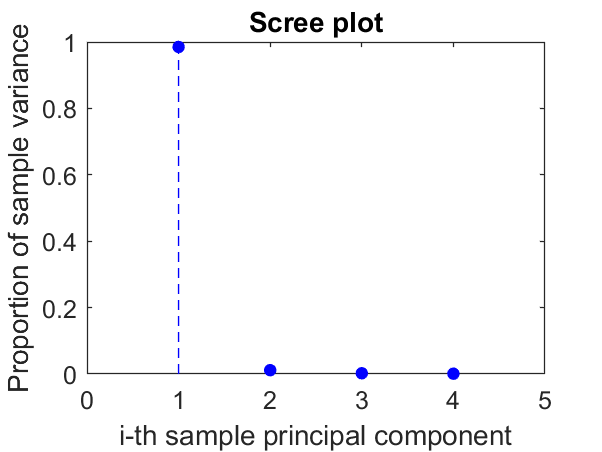

                               
figure();
plot([1:4],proportion,'b.','MarkerSize',16)
xlim([0 4+1]);
hold on
for k = 1:4
    N = 100;
    x = k*ones(N);
    y = linspace(0,proportion(k),N);
    plot(x,y,'b--')
end
xlabel('i-th sample principal component')
ylabel('Proportion of sample variance')
title('Scree plot')

It is pretty evident that the first component contain $98.5%$% of the total sample variance hence we could say that can be a useful approximation for our dataset. We want to further investigate with the cumulative proportion plot. The cumulative proportion plot is a chart which has on the *y_axis *the cumulative proportion of total sample variance explained by the $i_{th}$ component. While on the *x_axis *we have a label for each eigenvalue.

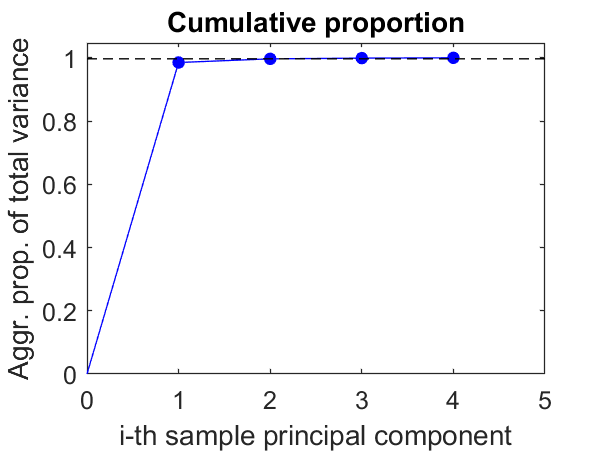

cumulative = cumsum(eig_val);         
cumulative_proportion = cumulative./total_variance; 
                                
figure();
plot([0:4],[0; cumulative_proportion], 'b-')
hold on
plot([1:4],cumulative_proportion,'b.','MarkerSize',16)
xlim([0 4+1])
ylim([0 1.05])
plot(linspace(0,4+1,100),cumulative_proportion(2)*ones(100),'k--')
                                            
xlabel('i-th sample principal component')
ylabel('Aggr. prop. of total variance')
title('Cumulative proportion')

Hence it can be seen that:

fprintf('The first sample principal component explains %.3f%% of variability\n', 100*cumulative_proportion(1))

The first sample principal component explains 98.513% of variability


We want to select the first sample principal component as it explain more than $98$% of variability in our dataset. Including the second principal component the gain in variability is not significant.

We can produce the sample principal components using linear combinations of the variables in the dataset. The coefficients of these linear combinations can be called loadings and correspond to the coordinates of the eigenvectors. 

The loadings of the first principal components are:

coeff(:,1)

ans =     0.2207
    0.1804
    0.0771
    0.9554


The first principal component is:


$$y = 0.22{x}_1 + 0.18{x}_2 + 0.08{x}_3 + 0.96{x}_4$$
